clc;
clear;
close all;

startup;

Loading: E:\ChalmersOnedrive\OneDrive - Chalmers\文档\chalmers\sensor fusion\SensorFusion\project\Sensorfusion smartphone\sensordata.jar


********************
* SensorDataReader started on 172.20.10.3:3401
********************
Connection accepted from 172.20.10.5:39336


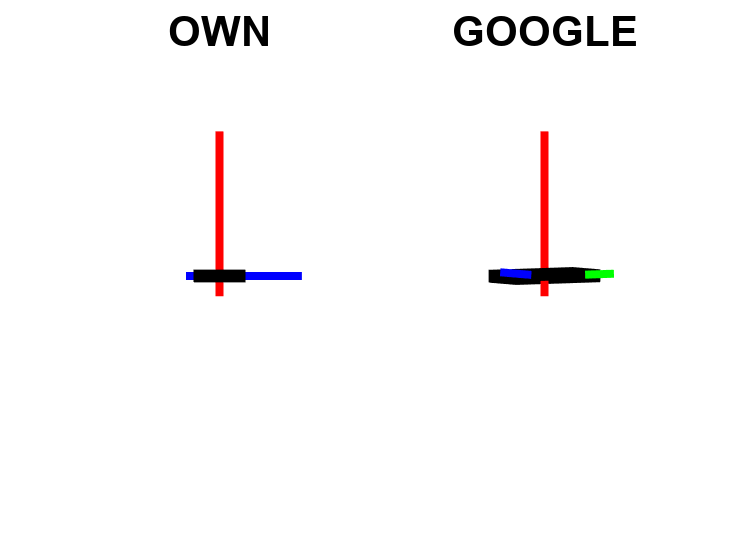

xhat = struct with fields:
    t: [0 0.0077 0.0177 0.0277 0.0350 0.0410 0.0470 0.0558 0.0658 0.0757 0.0853 0.0953 0.1053 0.1150 0.1250 0.1345 0.1445 0.1545 0.1642 0.1743 0.1843 0.1938 0.2038 0.2137 0.2235 0.2335 0.2430 0.2530 0.2630 0.2728 0.2828 0.2928 0.3023 0.3122 0.3220 … ]
    x: [4×1235 double]
    P: [4×4×1235 double]


meas = struct with fields:
         t: [0 0.0077 0.0177 0.0277 0.0350 0.0410 0.0470 0.0558 0.0658 0.0757 0.0853 0.0953 0.1053 0.1150 0.1250 0.1345 0.1445 0.1545 0.1642 0.1743 0.1843 0.1938 0.2038 0.2137 0.2235 0.2335 0.2430 0.2530 0.2630 0.2728 0.2828 0.2928 0.3023 0.3122 … ]
       acc: [3×1235 double]
       gyr: [3×1235 double]
       mag: [3×1235 double]
    orient: [4×1235 double]


[xhat, meas] = filterTemplate()

## plot

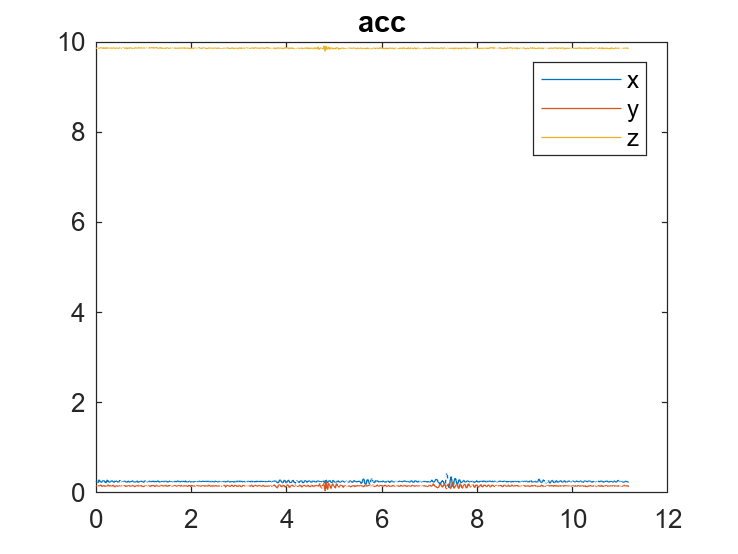


t= meas.t;
len = length(t);
figure;hold on;clf;
plot(t(:,1:len-10),meas.acc(:,1:len-10));
legend('x','y','z')
%the sequence is exactly xyz
title('acc');

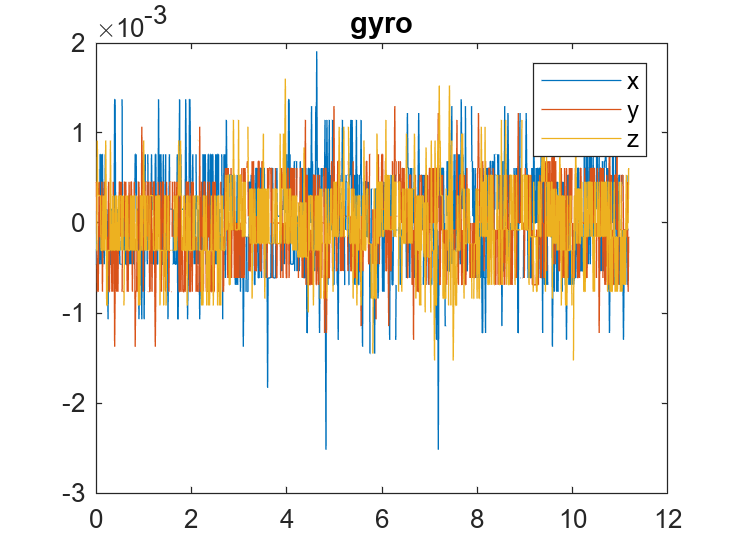

figure;hold on;clf;
plot(t(:,1:len-10),meas.gyr(:,1:len-10));
legend('x','y','z')
title('gyro');

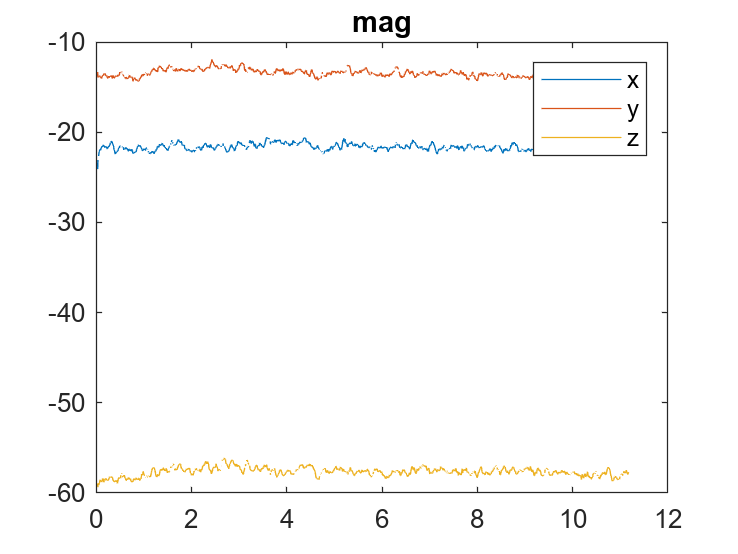

figure;hold on;clf;
plot(t(:,1:len-10),meas.mag(:,1:len-10));
legend('x','y','z')
title('mag');


% x_range = linspace(min(v), max(v), 100);
% % Plot the histogram of the innovation process
% figure(2); clf; hold on;
% histogram(v, 'Normalization', 'pdf','BinEdges',x_range);



## histogram & Gaussian

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of acc -X is 0.254171 
, the covariance of acc -X is 0.019724  

The mean of acc -Y is 0.157052 
, the covariance of acc -Y is 0.016096 

The mean of acc -Z is 9.862452 
, the covariance of acc -Z is 0.008445 



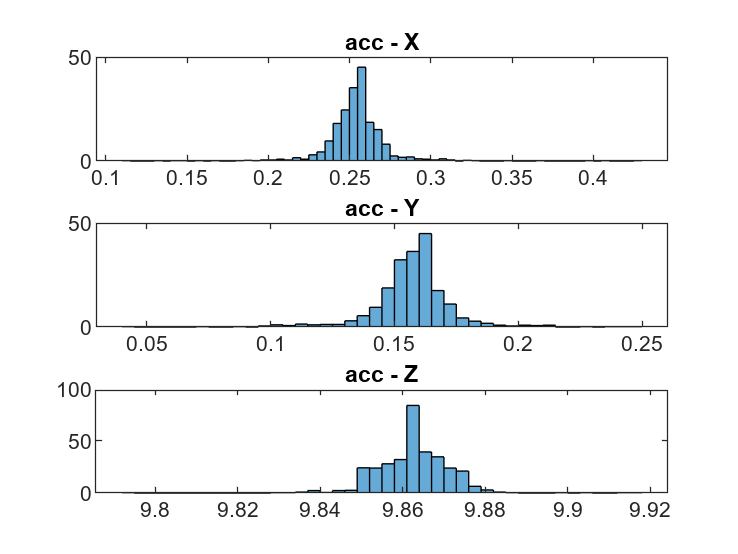

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% plot acc
plotHistograms(meas.acc, 'acc');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of gyro -X is 0.000014 
, the covariance of gyro -X is 0.000554  

The mean of gyro -Y is -0.000031 
, the covariance of gyro -Y is 0.000449 

The mean of gyro -Z is -0.000025 
, the covariance of gyro -Z is 0.000453 



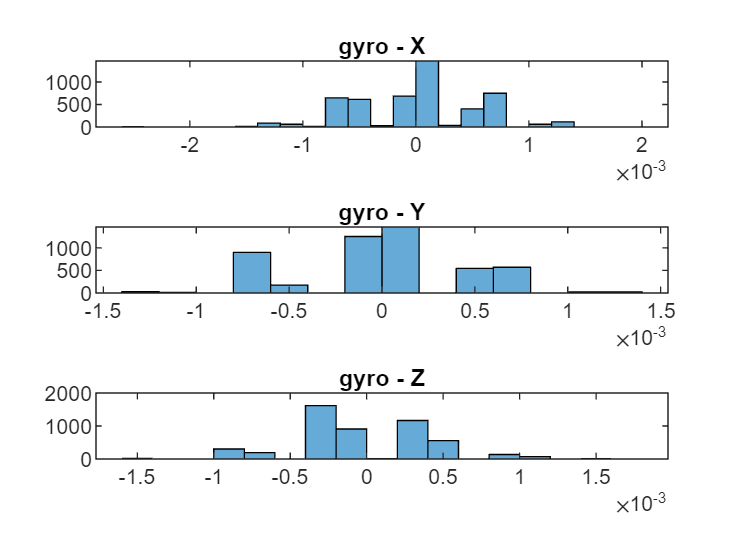

%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% plot gyro
plotHistograms(meas.gyr, 'gyro');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of mag -X is -21.648532 
, the covariance of mag -X is 0.377973  

The mean of mag -Y is -13.445163 
, the covariance of mag -Y is 0.401212 

The mean of mag -Z is -57.647071 
, the covariance of mag -Z is 0.477309 



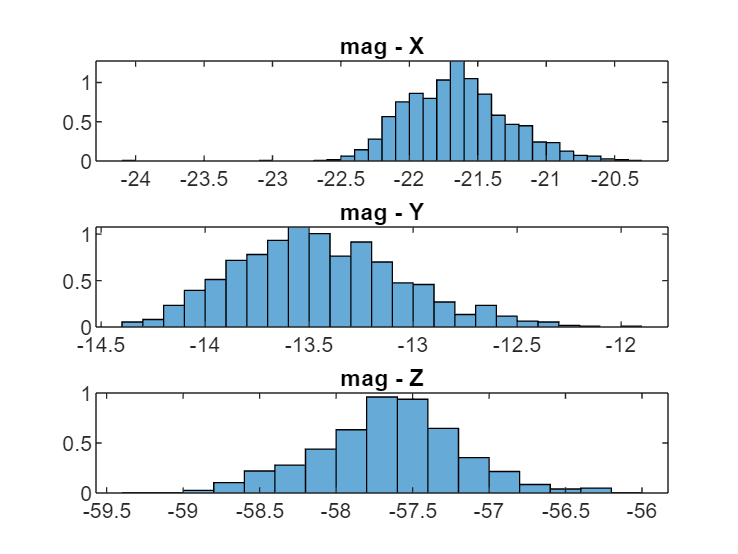

%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% plot mag
plotHistograms(meas.mag, 'mag');